clear
clf
load('data/gauntlet_scans.mat')

r = r_all(:,1);
theta = theta_all(:,1);

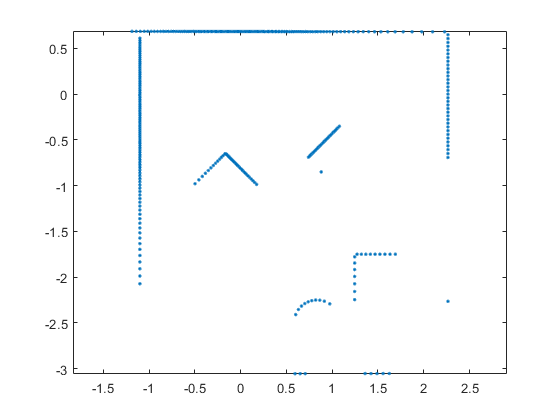

r_clean_index = find(r ~= 0);
r_clean = r(r_clean_index);
theta_clean = theta(r_clean_index);
[x, y] = pol2cart(theta_clean, r_clean);
points = [x y];
plot(x, y, '.')
axis equal

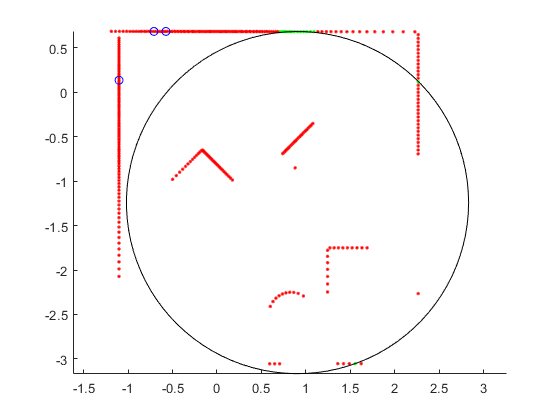

endpoints = 3×2 single matrix
   -0.7094    0.6850
   -0.5746    0.6848
   -1.1019    0.1353


inliers = 23×2 single matrix
   -0.5350    0.6848
   -0.5545    0.6848
   -0.5746    0.6848
   -0.5953    0.6849
   -0.6167    0.6849
   -0.6387    0.6849
   -0.6614    0.6849
   -0.6850    0.6850
   -0.7094    0.6850
   -0.7346    0.6850


outliers = 337×2 single matrix
    2.2645         0
    2.2645    0.0395
    2.2645    0.0791
    2.2645    0.1187
    2.2645    0.1583
    2.2645    0.1981
    2.2645    0.2380
    2.2645    0.2780
    2.2645    0.3183
    2.2645    0.3587


c = 1×2 single row vector
   -0.6426    0.2223


r = single
0.4675

d = 0.01;
n = 10000;
r_max = 0.5;
[endpoints, inliers, outliers, c, r] = ransac_circle_fit(points, r_max, d, n, 1)